Import CSV file

clearvars;
% filename = 'Data/20230322_1/400V_1.0MSs_5ohm_17_20230322103933251.5V_5ohm_-3V_ALL.csv';
filename = 'Data/20230322_1/400V_1.0MSs_5ohm_17_20230322104327251.5V_5ohm_-3V_ALL.csv';
data = readtable(filename);

Data parsing

data = renamevars(data, "Labels", "Time");
t = data.Time;
Vgs = data.Vgs;
Vds = data.Vds;
Id = data.Id;

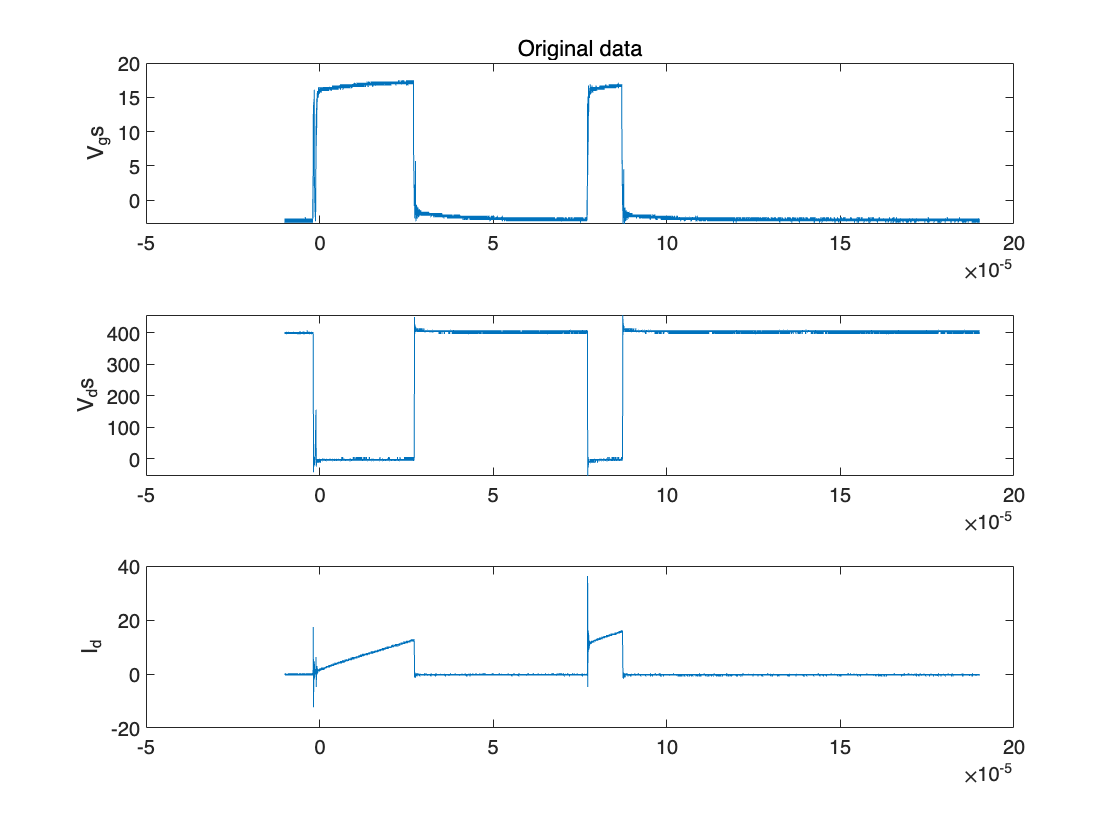

figure;

subplot(3,1,1);
plot(t, Vgs);
ylabel("V_gs");
title("Original data");

subplot(3,1,2);
plot(t, Vds);
ylabel("V_ds");

subplot(3,1,3);
plot(t, Id);
ylabel("I_d");

Perform continuous wavelet transform

fs = length(t)/(t(length(t)) - t(1))

fs = 6.2500e+09

[cfs_Id, f_Id] = cwt(Id, 'Morse', fs);
[cfs_Vds, f_Vds] = cwt(Vds, 'Morse', fs);
[cfs_Vgs, f_Vgs] = cwt(Vgs, 'Morse', fs);

Plot CWT data

% figure;
% hold on;
% imagesc([t(1) t(length(t))], [f_Id(1) f_Id(length(f_Id)) ], abs(cfs_Id)); % Plot the CWT coefficients using imagesc
% colormap(jet); % Choose the colormap for the CWT coefficients plot
% colorbar; % Show the color bar for the CWT coefficients
% xlabel('Time (s)');
% ylabel('Frequency (Hz)');
% % set(gca, 'YScale', 'log'); % Set the y-axis to log scale to better visualize the frequency components
% ylim([min(f_Id) max(f_Id)]); % Set the y-axis limits to match the range of analyzed frequencies
% hold off;

Reconstruct the data

Id_recon = icwt(cfs_Id, 'Morse', f_Id, [min(f_Id) max(f_Id)]);

Plot the original and recontruct data

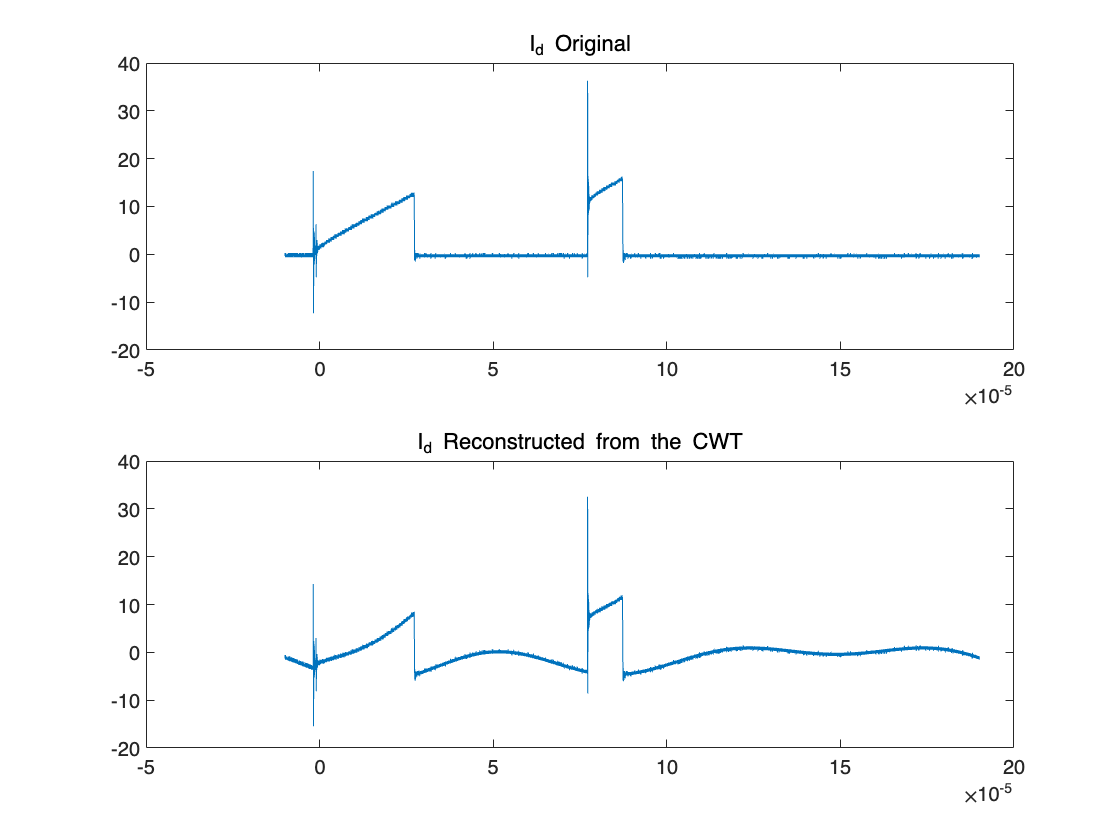

figure;

subplot(2,1,1);
plot(t, Id);
title("I_d Original");

subplot(2,1,2);
plot(t, Id_recon);
title("I_d Reconstructed from the CWT");

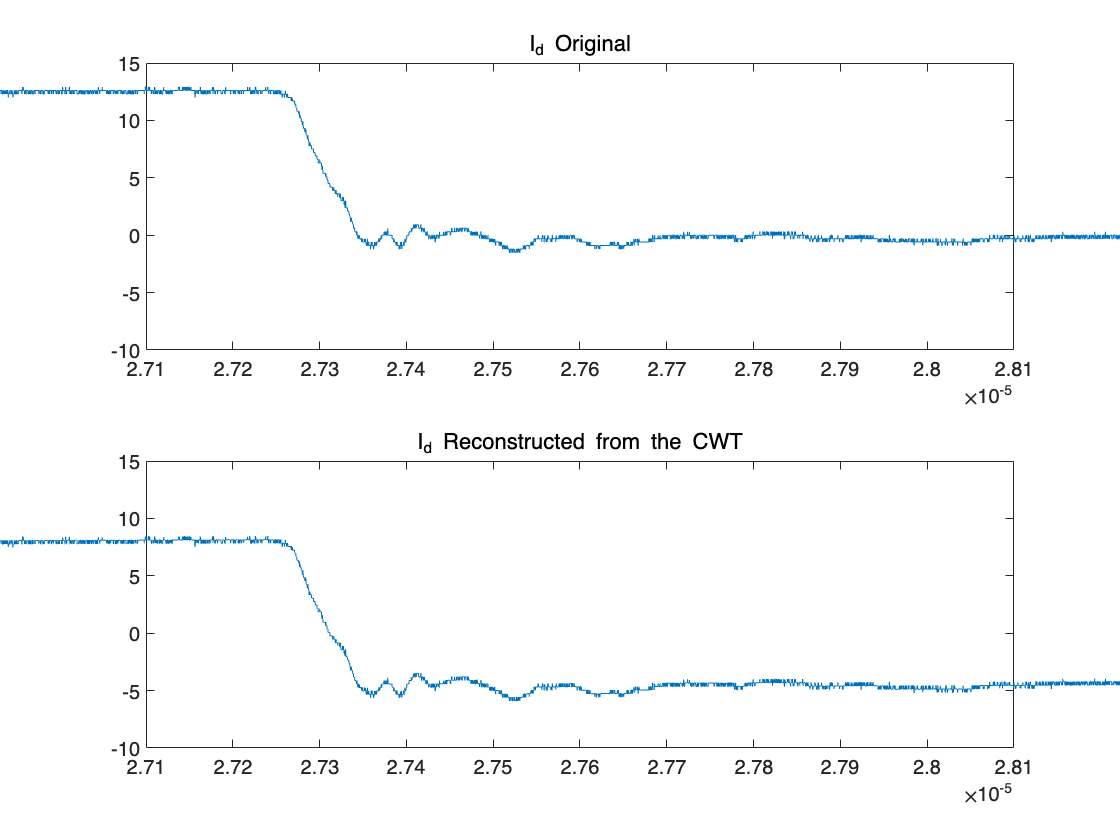

figure;
t_limit = 27.6e-6 + 0.5*[-1e-6 1e-6];

subplot(2,1,1);
plot(t, Id);
xlim(t_limit);
ylim([-10 15]);
title("I_d Original");

subplot(2,1,2);
plot(t, Id_recon);
xlim(t_limit);
ylim([-10 15]);
title("I_d Reconstructed from the CWT");

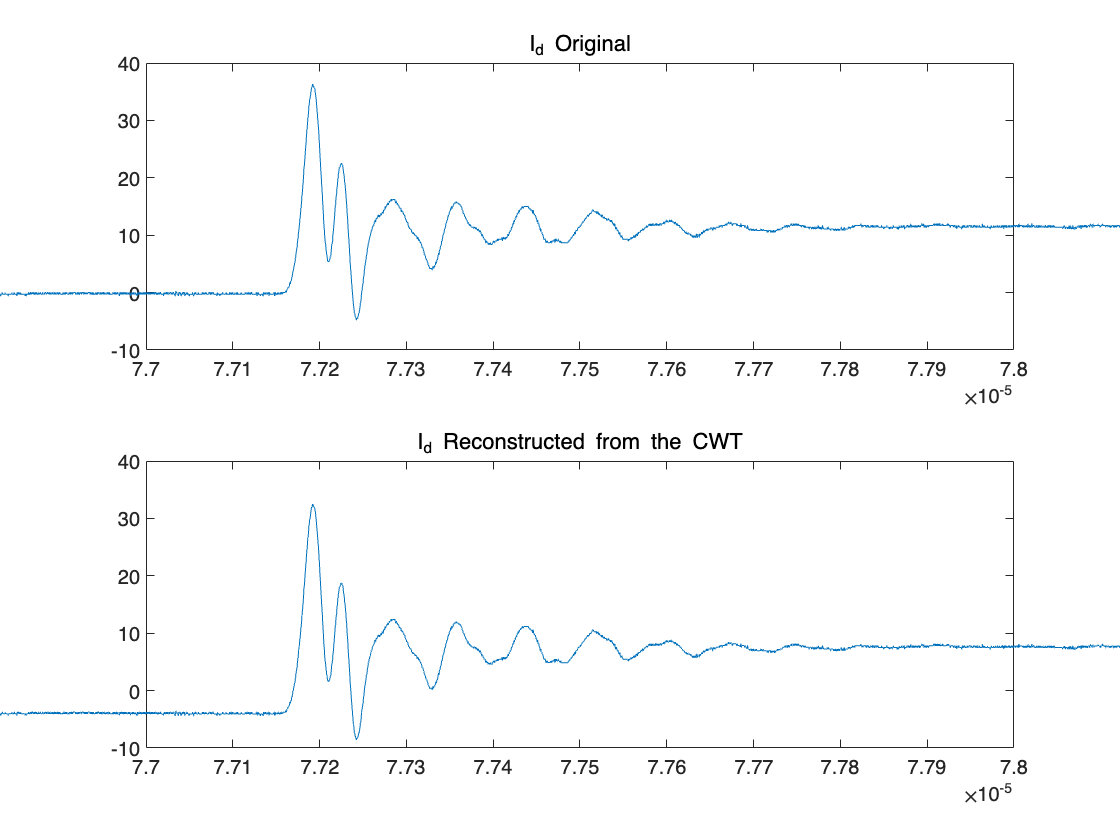

figure;
t_limit = 77.5e-6 + 0.5*[-1e-6 1e-6];

subplot(2,1,1);
plot(t, Id);
xlim(t_limit);
ylim([-10 40]);
title("I_d Original");

subplot(2,1,2);
plot(t, Id_recon);
xlim(t_limit);
ylim([-10 40]);
title("I_d Reconstructed from the CWT");